% creating a ground truth model
n_nodes = 30;
num_iter = 3; % number of max iterations

network_1_value = 5;
network_2_value = 8;

network_1 = [1 2 3 4 5];
network_2 = [9 12 13 14];
X_test = randn(n_nodes,1) / 3;

X_test_temp = zeros(n_nodes,1);
X_test_temp(network_1) = network_1_value;
X_test_temp(network_2) = network_2_value;
X_test = X_test + X_test_temp;

Y0 = X_test;

n_data = size(X_test,2);

M = full(DuplicationM(n_nodes));

%initialize parameters
Y = Y0;
Y_0.Y_opt = zeros([n_nodes,n_data]);
vechL_0.vechL = zeros(n_nodes * (n_nodes + 1) / 2, 1);

alpha = 2;

[L_iter,Y,vechl_result,Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Problem appears unbounded.

fminunc stopped because the objective function value is less than
or equal to the value of the objective function limit.

<stopping criteria details>
Finished 1 iteration with -152555274366258544640.00  and -152555274330954858496.00
Solving problem using fminco

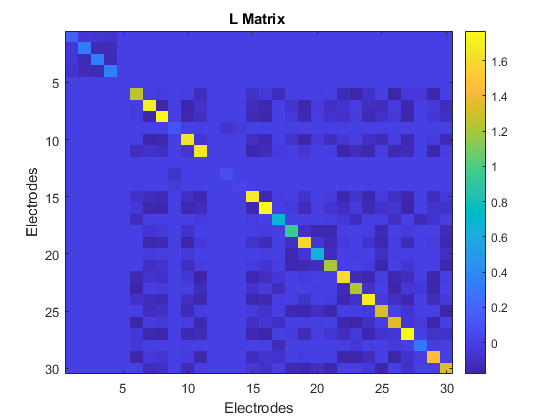


figure
imagesc(L_iter)
title('L Matrix ')
xlabel('Electrodes')
ylabel('Electrodes')
colorbar

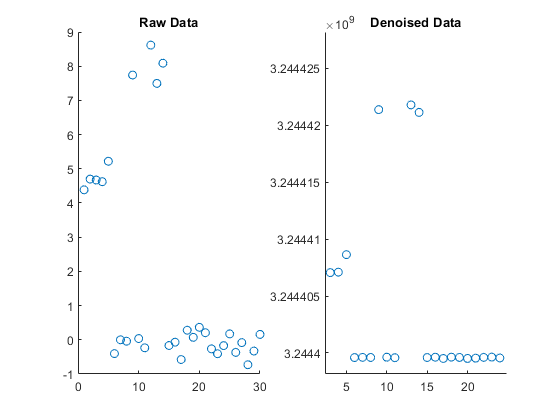


figure
subplot(1,2,1)
scatter(1:length(X_test),X_test)
title('Raw Data')

subplot(1,2,2)
scatter(1:length(Y),Y)
title('Denoised Data')



%then we look at spectral decomposition
[V,D] = eig(L_iter);

V =     0.1826    0.1033   -0.3874   -0.0366   -0.2260    0.0016   -0.0014   -0.8632   -0.0013   -0.0001   -0.0683   -0.0613    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1826    0.1035   -0.3875   -0.0367   -0.2355    0.0014    0.0005    0.3522    0.0008    0.0000   -0.7902   -0.0230   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1826    0.1035   -0.3874   -0.0367   -0.2368    0.0014    0.0004    0.2982    0.0007   -0.0001    0.4701   -0.6622   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1826    0.1035   -0.3874   -0.0367   -0.2358    0.0014    0.0003    0.2045    0.0005   

D =     0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0027         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.0045         0         0         0         0         0   

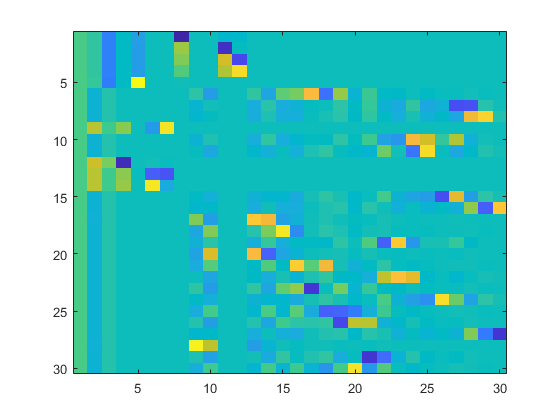

figure
imagesc(V)

This is somewhat working. We have some neighborhoods of correlated signal, one with the small neigiborhoods and the larger connected component in this matrix.  The problems are

- The algorithm is somewhat working. We can demonstrate the usage of graph search 